## 说明

在CSDN 上看到了一篇，关于“医学图像配准”的介绍

原文链接：[https://blog.csdn.net/u012258999/article/details/42972391](https://blog.csdn.net/u012258999/article/details/42972391) 

原始作者：godloveljw  

在原作者的基础上，调整了部分参数和图像显示

配准过程：

- 配置优化器和度量准则

- 提高配准精度

- 改变优化器的步长已达到对更加精细的变换

- 改变最大迭代次数

- 改变初始条件提高精度

## 读取系统图像（matlab自带的）

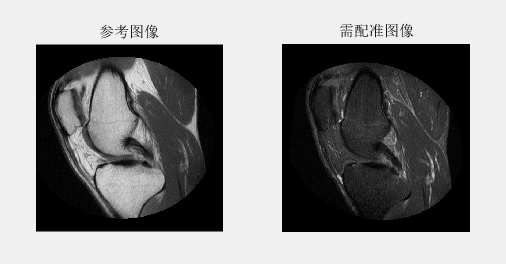

fixed = dicomread('knee1.dcm');      % 读参考图像fixed
moving = dicomread('knee2.dcm'); %  读浮动图像moving

## 配置优化器和度量准则

[optimizer, metric] = imregconfig('multimodal');

## 配准代码

movingRegisteredDefault = imregister(moving,fixed,'affine',optimizer,metric);

## 提高配准精度

disp('optimizer');

optimizer


disp('metric');

metric


## 改变优化器的步长已达到对更加精细的变换

optimizer.InitialRadius=optimizer.InitialRadius/3.5;
movingRegisteredAdjustedInitialRadius=imregister(moving,fixed,'affine',optimizer,metric);

## 改变最大迭代次数

optimizer.MaximumIterations = 300;
movingRegisteredAdjustedInitialRadius300 = imregister(moving, fixed, 'affine', optimizer, metric);

## 改变初始条件提高精度

tformSimilarity = imregtform(moving,fixed,'similarity',optimizer,metric);
Rfixed = imref2d(size(fixed));
movingRegisteredRigid = imwarp(moving,tformSimilarity,'OutputView',Rfixed);

movingRegisteredAffineWithIC = imregister(moving,fixed,'affine',optimizer,metric,'InitialTransformation',tformSimilarity);

## 绘制迭代过程

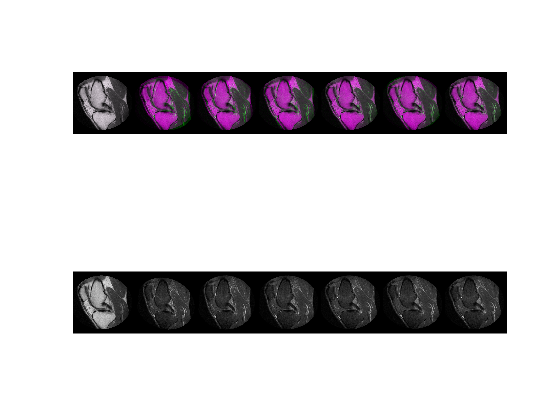

moving_new=[fixed,...
    moving,movingRegisteredDefault,...
    movingRegisteredAdjustedInitialRadius,...
    movingRegisteredAdjustedInitialRadius300,...
    movingRegisteredRigid,...
    movingRegisteredAffineWithIC    ];
fixed_new=[fixed,fixed,fixed,fixed,fixed,fixed,fixed,];
subplot(2,1,1);imshowpair(moving_new, fixed_new, 'falsecolor');
subplot(2,1,2);imshow(moving_new,[]);

## 绘制图像

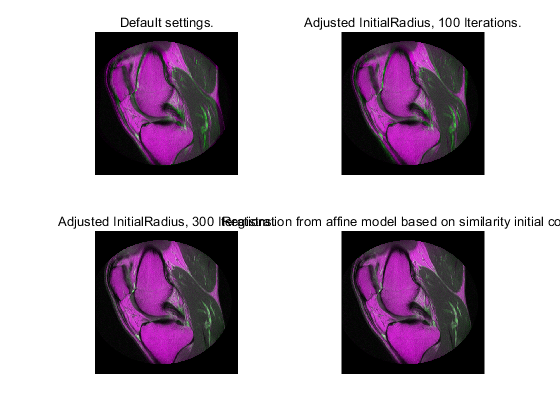

figure;
subplot(2,2,1);imshowpair(movingRegisteredDefault, fixed);
title('Default settings.');

subplot(2,2,2);
imshowpair(movingRegisteredAdjustedInitialRadius, fixed);
title('Adjusted InitialRadius, 100 Iterations.');

subplot(2,2,3);
imshowpair(movingRegisteredAdjustedInitialRadius300, fixed);
title('Adjusted InitialRadius, 300 Iterations.');

subplot(2,2,4);
imshowpair(movingRegisteredAffineWithIC, fixed);
title('Registration from affine model based on similarity initial condition.');